# Select GNSS Stations

In this workflow, choose which GNSS stations to include in processing.

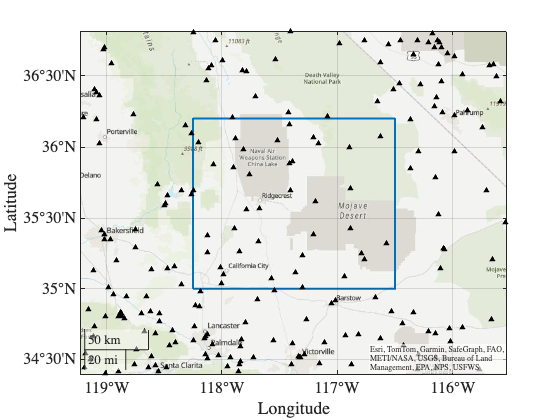

SelectUNRStations: 43 stations saved to /Volumes/Zel's Work Drive/Work/RidgecrestEQ/GNSS/allGNSSstations.txt


 
workdir= readlines("workdir.txt","EmptyLineRule","skip");

gnss.selectUNRStations(workdir);

 
workdir= readlines("workdir.txt","EmptyLineRule","skip");
GNSSdir= fullfile(workdir,'GNSS');
allStationsFile= fullfile(GNSSdir,'allGNSSstations.txt');

IDs= readlines(allStationsFile,"EmptyLineRule","skip");

fprintf("%s %s %s %s %s %s %s %s %s %s\n",IDs)

ARGU BEER BEPK CAC2 CCCC COSJ COSO CPBN DS13 DTPG
GOL2 GOL3 GOL4 GOLD HAPY HAR7 HMWD KENN LNMT P462
P463 P464 P568 P569 P579 P580 P590 P591 P592 P593
P594 P595 P596 P597 P615 P616 P617 P811 P812 PEAR
RAMT TOWG WORG 

 
workdir= readlines("workdir.txt","EmptyLineRule","skip");
GNSSdir= fullfile(workdir,'GNSS');
allStationsFile= fullfile(GNSSdir,'allGNSSstations.txt');

IDs= readlines(allStationsFile,"EmptyLineRule","skip");

rejectedGNSSfile= fullfile(GNSSdir,"rejectedGNSSstations.txt");
if exist(rejectedGNSSfile,'file')
    rejectedStations= readlines(rejectedGNSSfile,"EmptyLineRule","skip");
    
    fprintf("%s %s %s %s %s %s %s %s %s %s\n",setdiff(IDs,rejectedStations))
else
    fprintf("%s %s %s %s %s %s %s %s %s %s\n",IDs)
end

ARGU BEPK CCCC COSO CPBN DS13 DTPG GOLD HAR7 LNMT
P462 P463 P464 P568 P569 P579 P580 P590 P591 P592
P593 P594 P595 P596 P597 P615 P616 P617 RAMT TOWG
WORG 

 
workdir= readlines("workdir.txt","EmptyLineRule","skip");
GNSSdir= fullfile(workdir,'GNSS');
rejectedGNSSfile= fullfile(GNSSdir,"rejectedGNSSstations.txt");

if exist(rejectedGNSSfile,'file')
    rejectedStations= readlines(rejectedGNSSfile,"EmptyLineRule","skip");
    
    fprintf("%s %s %s %s %s %s %s %s %s %s\n",rejectedStations)
else
    fprintf("No rejected stations\n")
end

BEER BEPK CAC2 COSJ GOL2 GOL3 GOL4 HAPY HMWD KENN
P811 P812 PEAR 

## View Station Timeseries and Accept/Reject

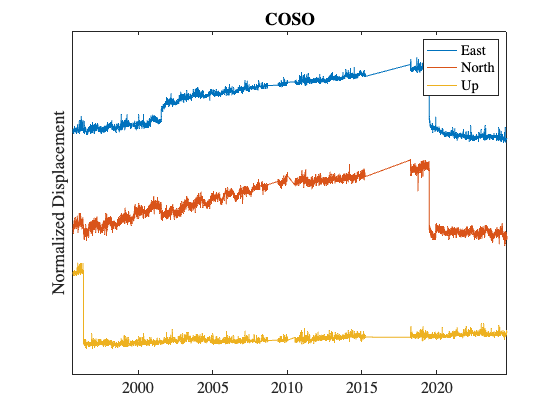

 
workdir= readlines("workdir.txt","EmptyLineRule","skip");
GNSSdir= fullfile(workdir,'GNSS');
allStationsFile= fullfile(GNSSdir,'allGNSSstations.txt');

IDs= readlines(allStationsFile,"EmptyLineRule","skip");

Nstations= length(IDs);

Index= 7;

ID= IDs(Index);

[Date,Displacement]= gnss.downloadUNRTimeseries(ID);

Demean= true;
if Demean
    Displacement= Displacement- mean(Displacement,'omitmissing');
end
Detrend= true;
if Detrend
    t= years(Date- Date(1));
    for i= 1:3
        I= ~isnan(Displacement(:,i));
        p= polyfit(t(I),Displacement(I,i),1);
        Displacement(:,i)= Displacement(:,i)- polyval(p,t);
    end
end
Separate= true;
if Separate
    Range= max(Displacement,[],'omitmissing')- min(Displacement,[],'omitmissing');
    Displacement= (Displacement- min(Displacement,[],'omitmissing'))./Range- 0.5+ 1.2*[1 0 -1];
end

plot(Date,Displacement)
title(ID)
plt.pltOptions
legend("East","North","Up")
if Separate
    ylabel("Normalized Displacement")
    yticks([])
else
    ylabel("Displacement (mm)") %#ok<*UNRCH>
end

rejectedGNSSfile= fullfile(GNSSdir,"rejectedGNSSstations.txt");

rejectedStations= [];
if exist(rejectedGNSSfile,'file')
    rejectedStations= readlines(rejectedGNSSfile,"EmptyLineRule","skip");
    
    if any(rejectedStations == ID)
        fprintf("Station %s is flagged as being rejected from the station pool.\n",ID)
    else
        fprintf("Station %s is accepted as a valid member of the station pool.\n",ID)
    end
else
    fprintf("Station %s is accepted as a valid member of the station pool.\n",ID)
end

Station COSO is accepted as a valid member of the station pool.


 
workdir= readlines("workdir.txt","EmptyLineRule","skip");
GNSSdir= fullfile(workdir,'GNSS');
rejectedGNSSfile= fullfile(GNSSdir,"rejectedGNSSstations.txt");

rejectedStations= [];
if exist(rejectedGNSSfile,'file')
    rejectedStations= readlines(rejectedGNSSfile,"EmptyLineRule","skip");
end

if isempty(rejectedStations)
    rejectedStations= ID;
else
    rejectedStations= setxor(rejectedStations,ID);
end

if isempty(rejectedStations)
    delete(rejectedGNSSfile)
else
    writelines(rejectedStations,rejectedGNSSfile)
end


if exist(rejectedGNSSfile,'file')
    rejectedStations= readlines(rejectedGNSSfile,"EmptyLineRule","skip");
    
    if any(rejectedStations == ID)
        fprintf("Station %s is flagged as being rejected from the station pool.\n",ID)
    else
        fprintf("Station %s is accepted as a valid member of the station pool.\n",ID)
    end
else
    fprintf("Station %s is accepted as a valid member of the station pool.\n",ID)
end

Station COSO is accepted as a valid member of the station pool.
